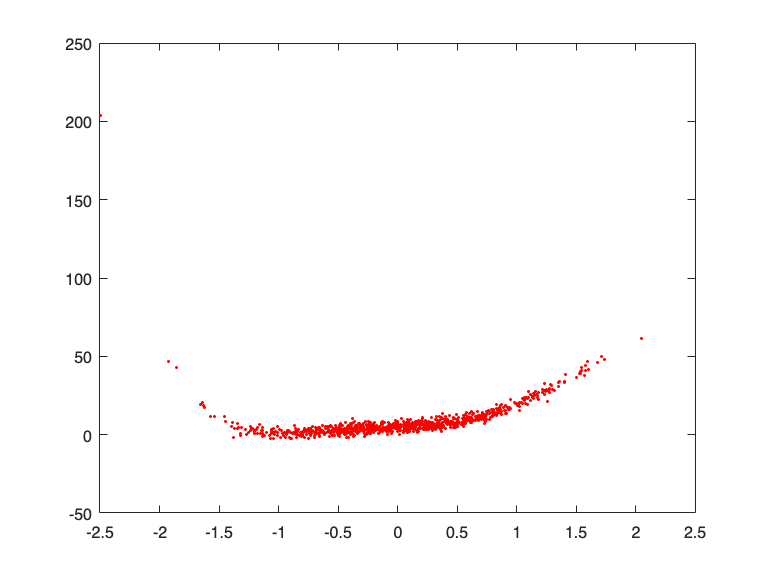

c = [-2 3 7 2 4 5];
x = randn(1,1000)/1.5;
y = polyval(c,x)+randn(size(x));
plot(x,y,'.r')

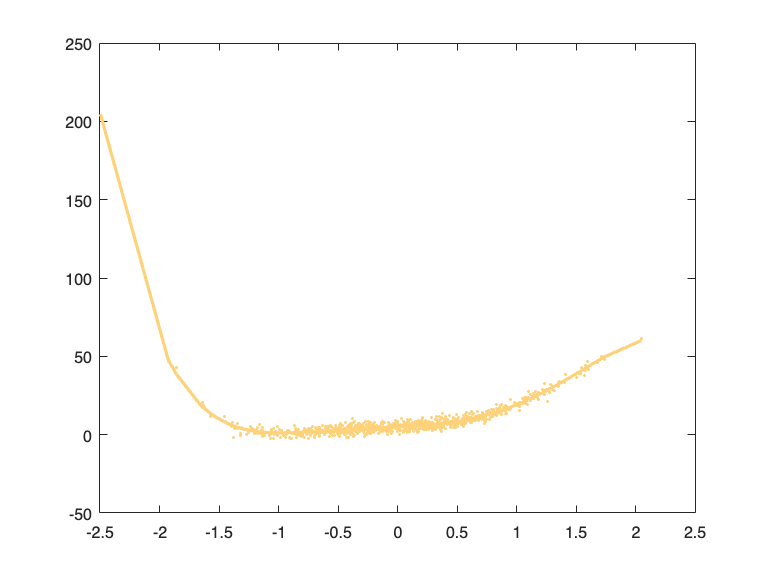

ctry =    -2.0347
    2.8035
    7.1411
    2.3777
    3.8891
    4.8257


r = 95.9907


[ctry, r] = getparams([x; y], 5)

A = [(x.^5)' (x.^4)' (x.^3)' (x.^2)' x' ones(size(x'))]

A =     0.0059    0.0165    0.0461    0.1285    0.3584    1.0000
    2.7315    2.2342    1.8274    1.4947    1.2226    1.0000
   -7.7442    5.1426   -3.4150    2.2677   -1.5059    1.0000
    0.0627    0.1091    0.1899    0.3304    0.5748    1.0000
    0.0004    0.0020    0.0096    0.0452    0.2125    1.0000
   -0.5036    0.5776   -0.6626    0.7600   -0.8718    1.0000
   -0.0020    0.0070   -0.0242    0.0836   -0.2891    1.0000
    0.0006    0.0027    0.0119    0.0522    0.2284    1.0000
   77.2656   32.3884   13.5766    5.6911    2.3856    1.0000
   21.4536   11.6199    6.2936    3.4088    1.8463    1.0000


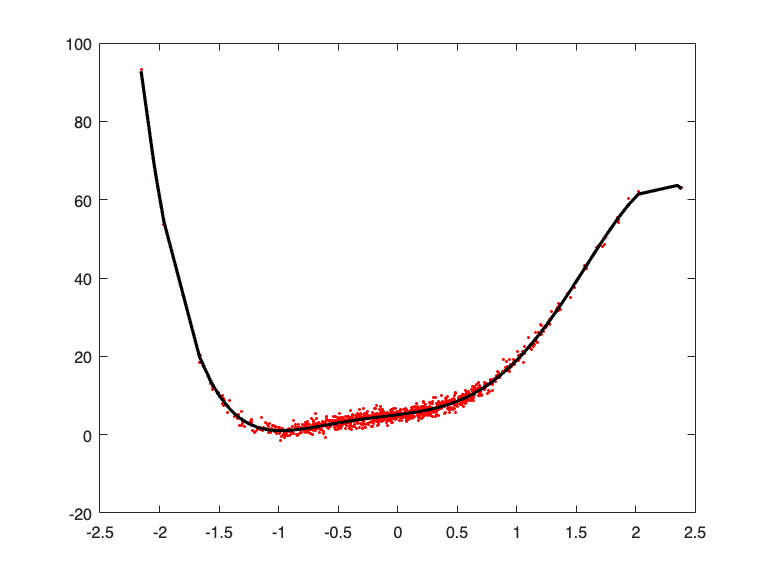

theta1 = A\y(:);
y1_hat = A*theta1;
[x1n, ind2n] = sort(x);
plot(x, y, '.r', x1n,y1_hat(ind2n), '-k', 'LineWidth',2)

[c' theta1]

ans =    -2.0000   -2.0201
    3.0000    2.9928
    7.0000    7.1100
    2.0000    1.9332
    4.0000    3.9037
    5.0000    5.0714


R2 = 100*(1-sum((y(:)-y1_hat(:)).^2)/sum((y(:)-mean(y(:))).^2))

R2 = 98.7734

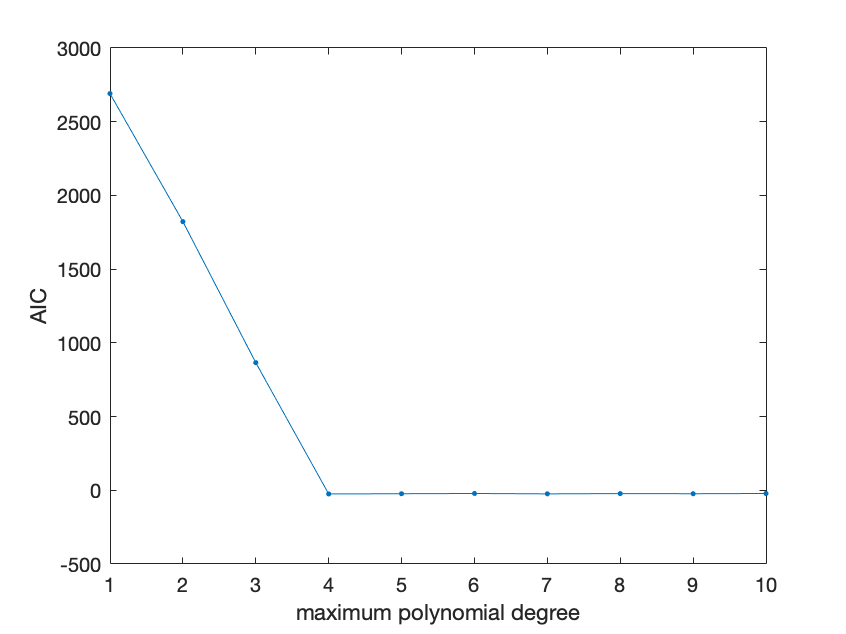

clear AIC
for k = 1:10
clear theta y_fit A
A = [];
for j = 0:1:k-1, A = [(x(:)).^j A]; end
theta = A\y(:);
y_fit = A*theta;
AIC(k) = numel(y)*log(1/(numel(y))*sum((y(:)-y_fit(:)).^2))+2*(k);
end
plot(AIC,'.-')
xlabel('maximum polynomial degree')
ylabel('AIC')

[~,optimalmodelorder] = min(AIC)

optimalmodelorder = 4